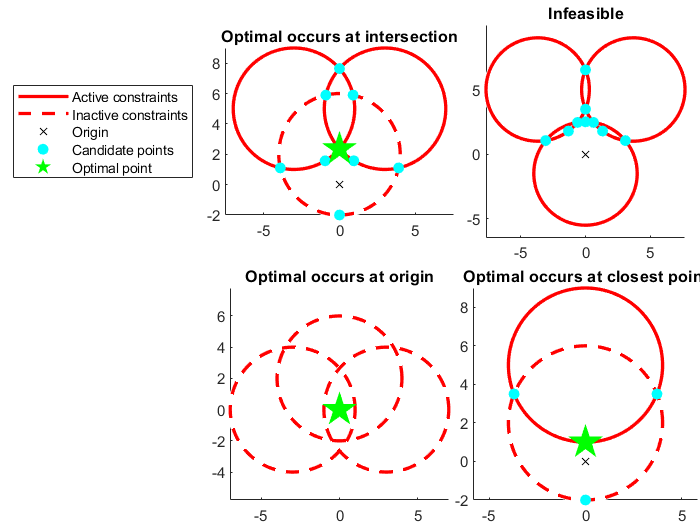

clear;close all
% 1: typical
% 2: tangent
% 3: infeasible constraint pair
% 4: infeasible constraint triplet
% 5: tangent plus intersect
% 6: origin feasible
% 7: redundant constraints and opt occurs on arc not intersect
paper = true; % true for 4 plots in paper, false for all test cases to debug
if paper
    testcases = [1 4 6 7];
    tiledlayout(2,2,'TileSpacing','tight','Padding','tight')
else
    testcases = 1:7;
end

for testcase = testcases
    run_testcase(testcase,paper)
end

function run_testcase(testcase,paper)
    % select inputs for this testcase
    x12_vec = [3 4 5 3.7  4 3 0];
    y3_vec  = [2 2 2 -1.5 1 2 2];
    y12_vec = [5 5 5 5    5 0 5];
    
    x = x12_vec(testcase);
    y3 = y3_vec(testcase);
    y12 = y12_vec(testcase);
    c = [x,y12;
        -x,y12;
         0,y3];
    r = [4;
         4;
         4];
    
    % run optimization
    [p_star,candidates,constraints_active] = circle_intersect_optim(c,r);
    
    % check testcases match desired outcomes
    should_be_feasible = [true true false false true true true];
    desired_constr_active = [2 2 3 3 3 0 2];

    if should_be_feasible(testcase)
        assert(~isempty(p_star))
    else
        assert(isempty(p_star))
    end
    assert(sum(constraints_active)==desired_constr_active(testcase))
    if testcase == 6
        assert(all(p_star==[0,0]))
    elseif any(testcase == [2,5])
        assert(ismembertol(p_star,[0 5],'ByRows',true))
    elseif testcase == 7
        assert(ismembertol(p_star,[0 1],'ByRows',true))
    end

    % plot
    if paper
        nexttile
        use_legend = testcase == 1;
    else
        figure
        use_legend = true;
    end
    plot_results(c,r,p_star,candidates,constraints_active,use_legend)
    titles = {'Optimal occurs at intersection','Tangent','Infeasible','Infeasible',...
        'Tangent plus intersect','Optimal occurs at origin','Optimal occurs at closest point'};
    if paper
        my_title = titles(testcase);
    else
        my_title = ['Testcase ' num2str(testcase)];
    end
    title(my_title)
end

function plot_results(c,r,p_star,candidates,constraints_active,use_legend)
    % active constraints
    hg_active = viscircles(c(constraints_active,:),r(constraints_active));
    axis equal
    hold on
    % inactive constraints
    hg_inactive = viscircles(c(~constraints_active,:),r(~constraints_active),'LineStyle','--');
    % origin
    ho = plot(0,0,'kx','DisplayName','Origin');
    % candidates
    hc = plot(candidates(:,1),candidates(:,2),'co','MarkerFaceColor','c','DisplayName','Candidate points');
    handles = [hg_active,hg_inactive,ho,hc];
    if ~isempty(p_star)
        hp = plot(p_star(1),p_star(2),'gp','MarkerFaceColor','g','MarkerSize',20,'DisplayName','Optimal point');
        handles = [handles hp];
    end
    % legend
    set(hg_active, 'DisplayName', 'Active constraints');
    set(hg_inactive, 'DisplayName', 'Inactive constraints');
    if use_legend
        legend(handles,'location','westoutside')
    end
end
